Load data.

clear
load('PowerChargerDataTable.mat')

Plot power usage in traditional charging station.

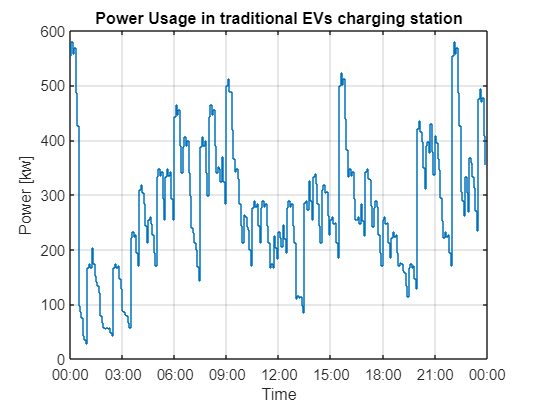

time = ChargerData.timestamp;
totalPower = ChargerData.ChargerPower.TotalkWhs;
totalPower = totalPower*(60*60); % convert kWh/s to kW
stairs(time, totalPower)
title('Power Usage in traditional EVs charging station')
datetick('x','HH:MM')
xlabel('Time')
ylabel('Power [kw]')
grid on

Set threshold value to start charge or discharge ESS.

pChgEss = 250;      % Start charging ESS after power usage drop below this value [kW]
pDscEss = 300;      % Start discharge ESS after power usage above this value [kW]

Set Energy capacity [Kwh] and E-rate for ESS. (assume charge and discharge rate is equal)

capa = 500;
Erate_dsc_onpeak = 1;
Erate_chg_onpeak = 0.05;
Erate_dsc_offpeak = 0.1;
Erate_chg_offpeak = 0.2;

Set initail and limit SoC of Ess.

soc = 0.28;
soc_min = 0.1;
soc_max = 1;

Set on/off peak time.

onPeakStr  = datetime(2023,11,9,9,0,0);     % on-peak time start from 9.00
offPeakStr = datetime(2023,11,9,22,0,0);    % off-peak time start from 22.00

Determine time step (dt) in seconds.

dt = [time; time(1)] - [time(1); time];
dt = dt(2:end-1);
dt = seconds(mean(dt));

ESS algorithm.

Pev = totalPower';
Pbatt = zeros(1,length(time));
Ebatt = zeros(1,length(time)+1);
Ebatt(1) = capa * soc;
Ebatt_min = capa * soc_min;
Ebatt_max = capa * soc_max;

% ESS use active sign convension
Pchg_max_onpeak  = -capa * Erate_chg_onpeak;
Pdsc_max_onpeak  =  capa * Erate_dsc_onpeak;
Pchg_max_offpeak  = -capa * Erate_chg_offpeak;
Pdsc_max_offpeak  =  capa * Erate_dsc_offpeak;

for i = 1:length(time)
    if Pev(i) < pChgEss                 % charge
        Pbatt(i) = -(pDscEss-Pev(i));   % Pbatt & Echg < 0

        % limit maximum power
        if (onPeakStr <= time(i)) && (time(i) < offPeakStr) % on-peak period
            Pbatt(i) = max(Pbatt(i), Pchg_max_onpeak);
        else                            % off-peak period
            Pbatt(i) = max(Pbatt(i), Pchg_max_offpeak);
        end
        
        Echg = Pbatt(i)*(dt/3600);  % calculate energy charge during this period
        
        if (Ebatt(i)-Echg) > Ebatt_max  % battery is full ?
            % limit the power to fully charge the battery in period
            Echg = -max(0, Ebatt_max-Ebatt(i)); % prevent discharging
            Pbatt(i) = Echg/(dt/3600);
        end
        
        Ebatt(i+1) = Ebatt(i) - Echg;

    elseif Pev(i) > pDscEss             % discharge
        Pbatt(i) = Pev(i)-pDscEss;      % Pbatt & Echg > 0
        
        % limit maximum power
        if (onPeakStr <= time(i)) && (time(i) < offPeakStr) % on-peak period
            Pbatt(i) = min(Pbatt(i), Pdsc_max_onpeak);
        else                            % off-peak period
            Pbatt(i) = min(Pbatt(i), Pdsc_max_offpeak);
        end
        
        Edsc = Pbatt(i)*(dt/3600);

        if (Ebatt(i)-Edsc) < Ebatt_min  % battery is deplete ?
            Edsc = max(0, Ebatt(i)-Ebatt_min);  % prevent charging
            Pbatt(i) = Edsc/(dt/3600);
        end
        
        Ebatt(i+1) = Ebatt(i) - Edsc;

    else    % no action needed
        Ebatt(i+1) = Ebatt(i);
    end
end

Pgrid_ems = Pev - Pbatt;
soc = (Ebatt(2:end)/capa)*100;

Plot grid power.

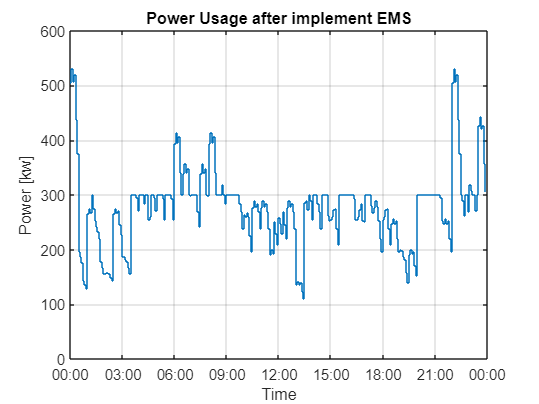

stairs(time, Pgrid_ems)
title('Power Usage after implement EMS')
datetick('x','HH:MM')
xlabel('Time')
ylabel('Power [kw]')
ylim([0 600])
grid on

Plot ESS SoC.

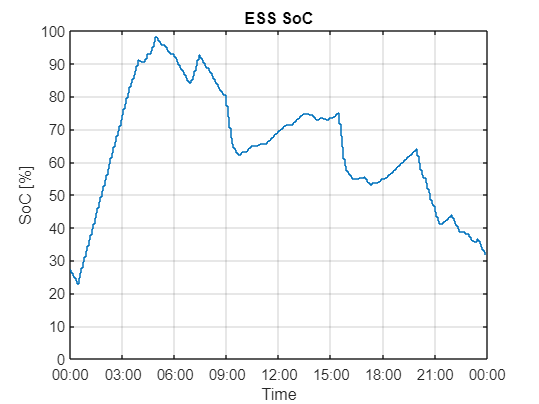

stairs(time, soc)
title('ESS SoC')
datetick('x','HH:MM')
xlabel('Time')
ylabel('SoC [%]')
ylim([0 100])
grid on

Plot ESS power.

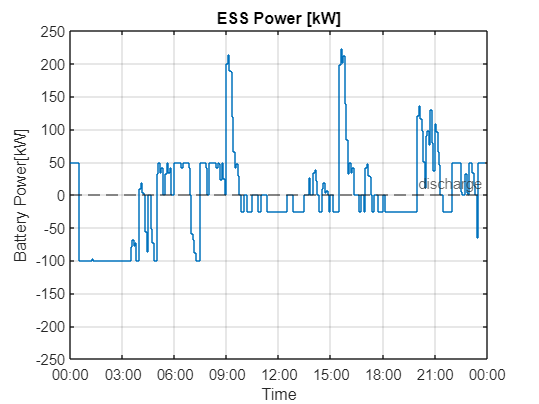

stairs(time, Pbatt)
yline(0, '--', 'discharge')
title('ESS Power [kW]')
datetick('x','HH:MM')
xlabel('Time')
ylabel('Battery Power[kW]')
ylim([-250 250])
grid on

Compare grid power.

stairs(time, Pev)
hold on
stairs(time, Pgrid_ems)
legend('without EMS', 'with EMS')
legend('Location', 'southeast')
title('Compare Power Usage')
datetick('x','HH:MM')
xlabel('Time')
ylabel('Power [kw]')
grid on

plot compare graph.

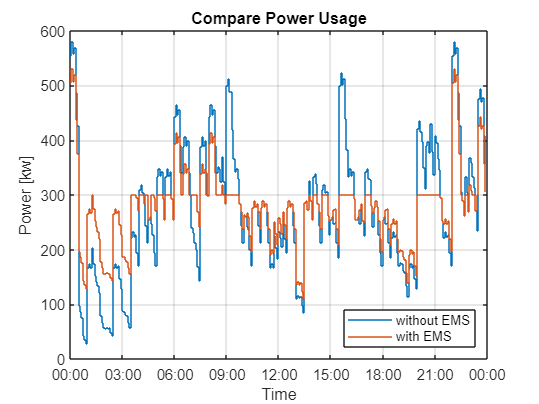

txt = sprintf(['Capacity: %d kWh, Onpeak charge: %.2fC, Onpeak discharge: %.2fC\n' ...
    'Offpeak charge: %.2fC, Offpeak discharge: %.2fC\n' ...
    'start discharge: %d kW, start charge: %d kW\n' ...
    '[off-peak charging only]'], ...
    capa, Erate_chg_onpeak ,Erate_dsc_onpeak, ...
    Erate_chg_offpeak ,Erate_dsc_offpeak, pDscEss, pChgEss);

tiledlayout(2,1)

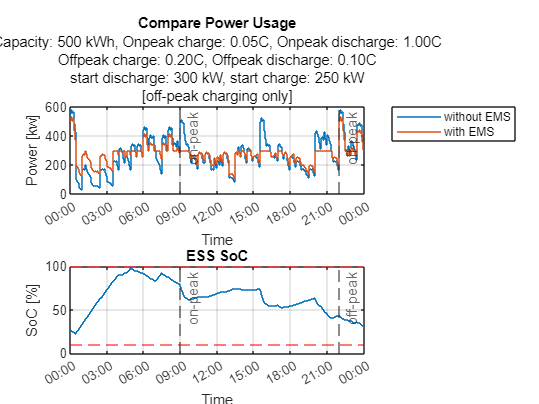

nexttile
stairs(time, Pev)       % without EMS
hold on
stairs(time, Pgrid_ems) % with EMS
xline(onPeakStr, '--', 'on-peak')
xline(offPeakStr, '--', 'off-peak')
legend('without EMS', 'with EMS')
legend('Location', 'northeastoutside')
title('Compare Power Usage', txt)
datetick('x','HH:MM')
xlabel('Time')
ylabel('Power [kw]')
grid on

nexttile
stairs(time, soc)
xline(onPeakStr, '--', 'on-peak')
xline(offPeakStr, '--', 'off-peak')
yline(soc_max*100, 'r--')
yline(soc_min*100, 'r--')
title('ESS SoC')
datetick('x','HH:MM')
xlabel('Time')
ylabel('SoC [%]')
ylim([0 100])
grid on

The previos algorithm design whether charge or discharge ESS based on current power usage without any prediction. We can improve this by using booking data as an load prediction and design the suitable time for charge ESS.

First we need to extract booking data. (assume all user are booked in advance)

charger_booked = ChargerData.ChargerPower{:,1:10} > 0;

assume power usage is constant 55 kW per charger.

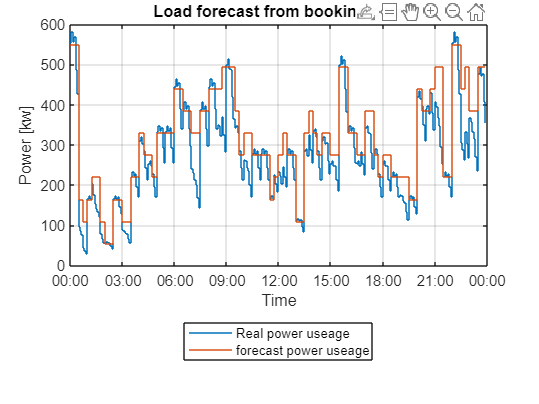

p_sch = sum(charger_booked, 2) .* 55;
figure
stairs(time, Pev)
hold on
stairs(time, p_sch)
title("Load forecast from booking data")
legend('Real power useage', 'forecast power useage')
legend('Location', 'southoutside')
datetick('x','HH:MM')
xlabel('Time')
ylabel('Power [kw]')
grid on

To be continue...